clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("八面安装点.xls");


phi = deg2rad(80);
phi = pi./2 - phi;
shenglunum = 9;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.02;



PAB = [1.987;-0.386;-0.153];
P_bound1 = num(1,[2,3,1]);
P_bound2 = num(2,[2,3,1]);

xl = num(6,~isnan(num(6,:)));
yl = num(7,~isnan(num(7,:)));
zl = num(5,~isnan(num(5,:)));
side_faces_transformed1 =[xl;yl;zl];

xt = num(11,~isnan(num(11,:)));
yt = num(12,~isnan(num(12,:)));
zt = num(10,~isnan(num(10,:)));
side_faces_transformed3 =[xt;yt;zt];

xr = num(16,~isnan(num(16,:)));
yr = num(17,~isnan(num(17,:)));
zr = num(15,~isnan(num(15,:)));
side_faces_transformed5 =[xr;yr;zr];


xb = num(21,~isnan(num(21,:)));
yb = num(22,~isnan(num(22,:)));
zb = num(20,~isnan(num(20,:)));
side_faces_transformed7 =[xb;yb;zb];


xlb = num(26,~isnan(num(26,:)));
ylb = num(27,~isnan(num(27,:)));
zlb = num(25,~isnan(num(25,:)));
side_faces_transformed8 =[xlb;ylb;zlb];


xlt = num(31,~isnan(num(31,:)));
ylt = num(32,~isnan(num(32,:)));
zlt = num(30,~isnan(num(30,:)));
side_faces_transformed2 =[xlt;ylt;zlt];


xrt = num(36,~isnan(num(36,:)));
yrt = num(37,~isnan(num(37,:)));
zrt = num(35,~isnan(num(35,:)));
side_faces_transformed4 =[xrt;yrt;zrt];

xrb = num(41,~isnan(num(41,:)));
yrb = num(42,~isnan(num(42,:)));
zrb = num(40,~isnan(num(40,:)));
side_faces_transformed6 =[xrb;yrb;zrb];


side_faces_transformed2 = [];
% side_faces_transformed4 = [];

[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,0.2);

Isempty FACE2468: 0.000000, 12.000000, 12.000000, 12.000000


Ti = ShengDaoGaoDu(shenglunum);
[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 0.000000, 12.000000, 12.000000, 12.000000


PointTable_A_off8 =    -0.9263   -0.7302   -0.4110    0.0188    0.5008    0.9828    1.4127    1.7437    1.9271    1.9366    1.7405    1.4230    0.9932    0.5112    0.0291   -0.4007   -0.7199   -0.9167
   -1.7882   -1.9042   -2.0443   -2.0455   -2.0468   -2.0481   -2.0493   -2.0502   -2.0475    1.6940    1.8336    1.9803    1.9815    1.9828    1.9841    1.9853    1.8432    1.7184
   -0.4569   -0.4858   -0.5205   -0.5202   -0.5199   -0.5195   -0.5192   -0.5190   -0.5181    0.4209    0.4557    0.4920    0.4917    0.4914    0.4911    0.4908    0.4547    0.4231


PointTable_B_off8 =    -0.9180   -0.7214   -0.4016    0.0282    0.5102    0.9923    1.4221    1.7518    1.9359    1.9279    1.7315    1.4136    0.9838    0.5017    0.0197   -0.4101   -0.7288   -0.9250
    1.5367    1.6485    1.7791    1.7779    1.7766    1.7753    1.7741    1.6406    1.5225   -1.8416   -1.8440   -1.8431   -1.8419   -1.8406   -1.8393   -1.8381   -1.7122   -1.6081
    0.8690    0.9325    1.0070    1.0073    1.0076    1.0079    1.0082    0.9335    0.8671   -1.0334   -1.0352   -1.0354   -1.0357   -1.0360   -1.0364   -1.0367   -0.9662   -0.9078


XieMianPianYi =     0.0097    0.0097         0         0         0         0         0    0.0109    0.0109    0.0108         0         0         0         0         0         0    0.0090    0.0090


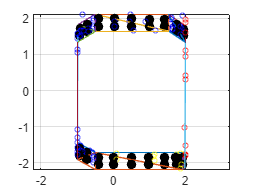

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(1,:),side_faces_transformed1(2,:),side_faces_transformed1(3,:),15,'yellow')
% scatter3(side_faces_transformed2(1,:),side_faces_transformed2(2,:),side_faces_transformed2(3,:),15,'green')
scatter3(side_faces_transformed3(1,:),side_faces_transformed3(2,:),side_faces_transformed3(3,:),15,'red')
scatter3(side_faces_transformed4(1,:),side_faces_transformed4(2,:),side_faces_transformed4(3,:),15,'blue')
scatter3(side_faces_transformed5(1,:),side_faces_transformed5(2,:),side_faces_transformed5(3,:),15,'blue')
scatter3(side_faces_transformed6(1,:),side_faces_transformed6(2,:),side_faces_transformed6(3,:),15,'blue')
scatter3(side_faces_transformed7(1,:),side_faces_transformed7(2,:),side_faces_transformed7(3,:),15,'blue')
scatter3(side_faces_transformed8(1,:),side_faces_transformed8(2,:),side_faces_transformed8(3,:),15,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end


% scatter3(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),150,'filled','r')
% scatter3(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),150,'filled','g')
% scatter3(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),150,'filled','b')
% scatter3(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),150,'filled','c')
% scatter3(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),150,'filled','m')
% scatter3(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),150,'filled','y')
% scatter3(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),150,'filled','k')
scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')


% PP16 = TrianglePoints8(:,[7,8,14,20,26,32,38,44,3,9,18,24,30,36,42,48]);
% scatter3(PP16(1,2),PP16(2,2),PP16(3,2),50,'filled','red');
% scatter3(PP16(1,3),PP16(2,3),PP16(3,3),50,'filled','green');




## 点测试

% [PlaneParaOut4,TrianglePoints4,~,~] = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
% [Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints4)
% PP =PP';
% scatter3(PP(1,1),PP(2,1),PP(3,1),50,'r','filled')
% scatter3(PP(1,2),PP(2,2),PP(3,2),50,'g','filled')
% scatter3(PP(1,3),PP(2,3),PP(3,3),50,'b','filled')
% scatter3(PP(1,4),PP(2,4),PP(3,4),50,'c','filled')
% scatter3(PP(1,5),PP(2,5),PP(3,5),50,'m','filled')
% scatter3(PP(1,6),PP(2,6),PP(3,6),50,'y','filled')
% scatter3(PP(1,7),PP(2,7),PP(3,7),50,'k','filled')
% scatter3(PP(1,8),PP(2,8),PP(3,8),50,'r','filled')
% 
% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')
% toff = [-a(1:shenglunum)./tan(phi),a(1:shenglunum)./tan(phi)];
% [PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)
% 
% 
% scatter3(PointTable_B_off(1,1),PointTable_B_off(2,1),PointTable_B_off(3,1),150,'filled','r')
% scatter3(PointTable_B_off(1,2),PointTable_B_off(2,2),PointTable_B_off(3,2),150,'filled','g')
% scatter3(PointTable_B_off(1,3),PointTable_B_off(2,3),PointTable_B_off(3,3),150,'filled','b')
% scatter3(PointTable_B_off(1,4),PointTable_B_off(2,4),PointTable_B_off(3,4),150,'filled','c')
% scatter3(PointTable_B_off(1,5),PointTable_B_off(2,5),PointTable_B_off(3,5),150,'filled','m')
% scatter3(PointTable_B_off(1,6),PointTable_B_off(2,6),PointTable_B_off(3,6),150,'filled','y')
% 
% 
% scatter3(PointTable_B_off(1,8),PointTable_B_off(2,8),PointTable_B_off(3,8),150,'filled','k')
% scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','black')